# Análisis de Robot lineal de 3GDL

Para esta actividad calcularemos la matriz de la velocidad lineal y agunlar del siguiete sistema:

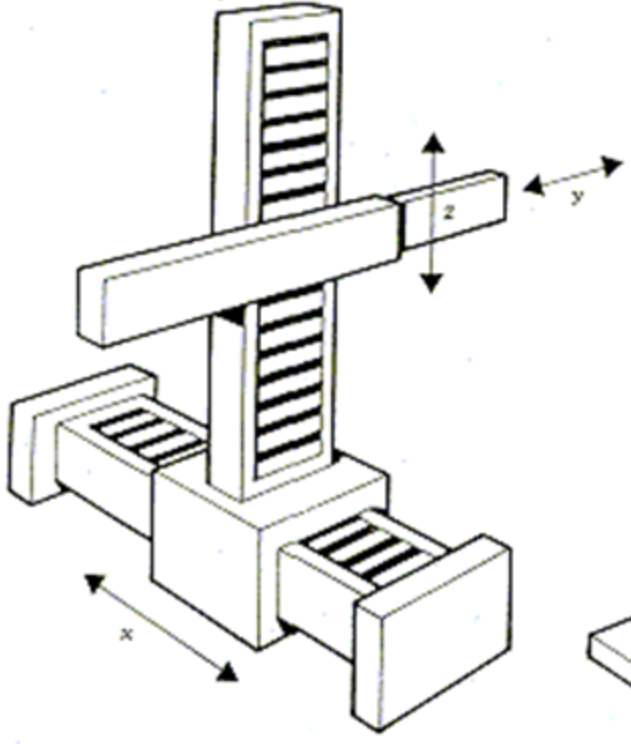

Empezamos con la declaración de las variables simbólicas l1, l2, l3 y t. También especificamos el tipo de configuración para cada una de las juntas del robot y creamos el vector de velocidades generalizadas:

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms l1(t) l2(t) l3(t) t 

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Creamos el vector de coordenadas articulares
Q= [l1, l2, l3];

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Para la articulación 1, notamos con ayuda de la regla de la mano derecha que requerimos un giro de -90° respecto a y y para la articulación 2 igual aplicando la regla de la mano derecha notamos que se requiere un giro de -90° respecto a x, Y por ultimo para la articulación 3 ya no requerimos hacer alguna rotación puesto que ya nos encontramos en el punto en el que se encuentra.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,1)= [0  0 -1 ;
           0  1  0;
           1  0  0];

%Articulación 2 
%Posición de la articulación 3 respecto a 0
P(:,:,2)= [0 ; l2; l3];
%Matriz de rotación de la junta 3 respecto a 0.... 90º x1 
R(:,:,2)= [1  0  0;
           0  0  1;
           0  1  0];

%Articulación 3 
%Posición de la articulación 3 respecto a 0
P(:,:,3)= [0 ; 0; 0];
%Matriz de rotación de la junta 3 respecto a 0.... 90º x1 
R(:,:,3)= [0  0  0;
           0  0  0;
           0  0  0];

Ya que contamos con las matrices posicional y de rotación para cada una de las juntas podemos calcular la velocidad angular y lineal del sistema como lo hemos echo en actividades anteriores:

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
end

Matriz de Transformación local A1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación global T1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación local A2


/ 1, 0, 0,   0   \
|                |
| 0, 0, 1, l2(t) |
|                |
| 0, 1, 0, l3(t) |
|                |
\ 0, 0, 0,   1   /



Matriz de Transformación global T2


/ 0, -1, 0, -l3(t) \
|                  |
| 0,  0, 1,  l2(t) |
|                  |
| 1,  0, 0,  l1(t) |
|                  |
\ 0,  0, 0,    1   /



Matriz de Transformación local A3


/ 0, 0, 0, 0 \
|            |
| 0, 0, 0, 0 |
|            |
| 0, 0, 0, 0 |
|            |
\ 0, 0, 0, 1 /



Matriz de Transformación global T3


/ 0, 0, 0, -l3(t) \
|                 |
| 0, 0, 0,  l2(t) |
|                 |
| 0, 0, 0,  l1(t) |
|                 |
\ 0, 0, 0,    1   /




%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%Derivadas parciales de x respecto a th1, th3 y th2
Jv11= functionalDerivative(PO(1,1,GDL), l1);
Jv12= functionalDerivative(PO(1,1,GDL), l2);
Jv13= functionalDerivative(PO(1,1,GDL), l3);
%Derivadas parciales de y respecto a th1, th3 y th2
Jv21= functionalDerivative(PO(2,1,GDL), l1);
Jv22= functionalDerivative(PO(2,1,GDL), l2);
Jv23= functionalDerivative(PO(2,1,GDL), l3);
%Derivadas parciales de z respecto a th1, th3 y th2
Jv31= functionalDerivative(PO(3,1,GDL), l1);
Jv32= functionalDerivative(PO(3,1,GDL), l2);
Jv33= functionalDerivative(PO(3,1,GDL), l3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
               Jv21 Jv22 Jv23;
               Jv31 Jv32 Jv33]);
pretty(jv_d);

/ 0, 0, -1 \
|          |
| 0, 1,  0 |
|          |
\ 1, 0,  0 /





%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, -1, 0 \
|          |
| 0,  0, 1 |
|          |
\ 1,  0, 0 /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 0, 0, 0 /





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   ________ \
|    d       |
| - -- l2(t) |
|   dt       |
|            |
|  ________  |
|   d        |
|  -- l3(t)  |
|  dt        |
|            |
|  ________  |
|   d        |
|  -- l1(t)  |
\  dt        /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



## RESULTADOS:

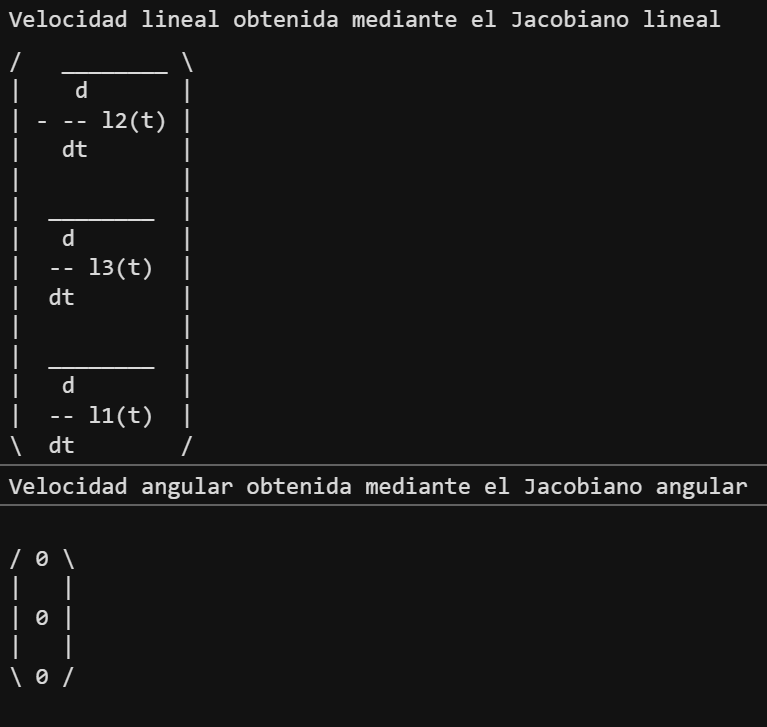

Podemos observar que tenemos una matriz de ceros para nuestra velocidad angular ya que nuestro sistema no cuenta con articulaciones rotacionales, Sin Embargo para la velocidad linear podemos ver que tenemos l1, l2 y l3 repartidas en cada uno de nuestros vectores en "x", "y" y "z", esto es debido a que tenemos una articulación prismática en cada dimensión, haciéndolas responsables de la velocidad lineal de la dimensión en la que se encuentren.